clear
load ue_03_preprocessing_data
whos

  Name                       Size             Bytes  Class       Attributes

  DateTime               43848x1             701569  datetime              
  Q_COL                  43848x1             350784  double                
  Q_USL                  43848x1             350784  double                
  TETA_S_D_VWC_10_A      43848x1             350784  double                
  TETA_S_D_VWC_50_A      43848x1             350784  double                



### Gapfilling: fill gaps with linear interpolation

WC_10 = TETA_S_D_VWC_10_A;
WC_50 = TETA_S_D_VWC_50_A;

TT = timetable(DateTime,WC_10,WC_50);
S = timerange('1-June-2015 00:00:00','1-Sep-2015 00:00:00');
TT2 = TT(S,:);
WC2015 = fillmissing(TT2,'linear');

Plotting the raw data and filled data

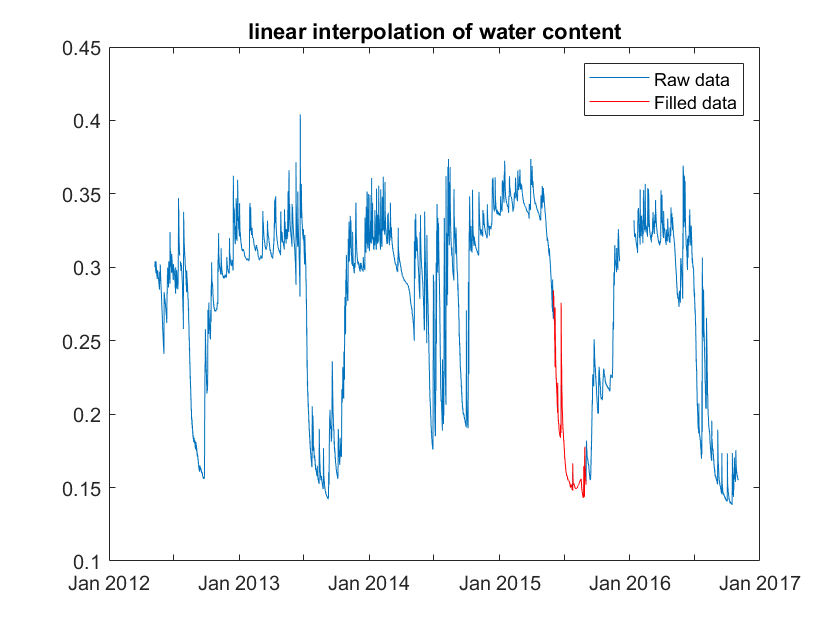

plot(DateTime,WC_10,'-')
hold on
plot(WC2015.DateTime,WC2015.WC_10,'-','Color','r')
hold off
legend('Raw data','Filled data')
title('linear interpolation of water content')

    Evaluate the gap-filled time series

The linear interpolation of the water content appears well-fit to the remaining data regarding the trend and the amplitude of variation. It does have less frequency of peak and it may be explained by the indense known data point. It is still reasonable given the limitations.

### Normalization

QUSL_mean = nanmean(Q_USL); %mean for discharge data
QCOL_mean = nanmean(Q_COL);
QUSL_sd = nanstd(Q_USL);%standard deviation 
QCOL_sd = nanstd(Q_COL);
nl_QUSL = (Q_USL - QUSL_mean)/QUSL_sd;
nl_QCOL = (Q_COL - QCOL_mean)/QCOL_sd;

        Creating two subplots

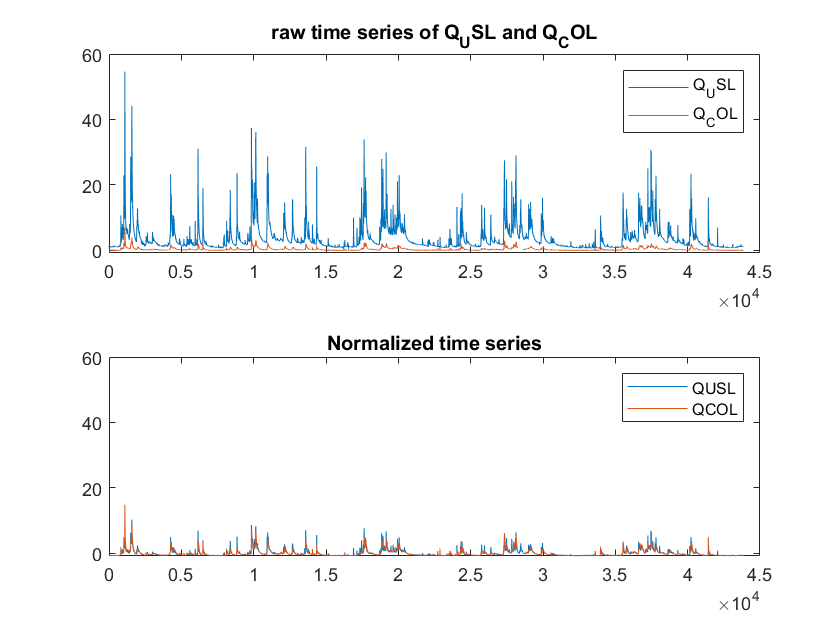

figure
tiledlayout(2,1)
ax1 = nexttile;
plot(Q_USL)
hold on 
plot(Q_COL)
title('raw time series of Q_USL and Q_COL')
legend('Q_USL','Q_COL')

ax2 = nexttile;
plot(nl_QUSL)
hold on
plot(nl_QCOL)
title('Normalized time series')
legend('QUSL','QCOL')


%linking the time axis between two subplots
hold off
linkaxes([ax1 ax2],'xy')

The normalized data of the two discharge time series agree in a much greater extent than the raw data. The amplitude of QUSL have been greatly suppressed. The scales of the data are more comparable after normalization. The correlation/ similiarity of the trend in the time series can be easily observed after processing. 

### Smoothing: Moving average filter

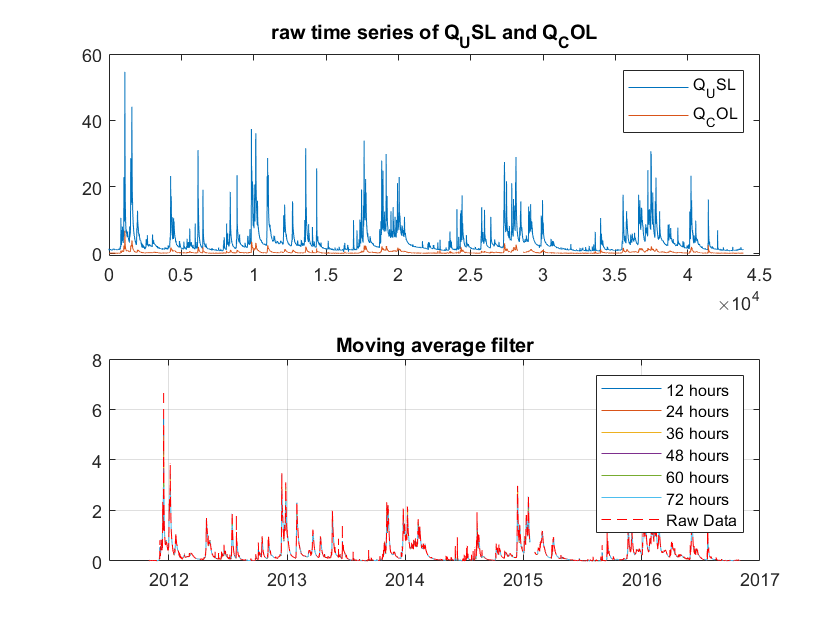

window_size = [12, 24, 36, 48, 60, 72]; %window size vector
Datapoint = size(Q_COL,1);
QCOL_movmean = zeros(Datapoint,6); %to store the moving means results

for k = 1:length(window_size) %for loop to operate moving mean
  QCOL_movmean(:,k) = movmean(Q_COL,window_size(k),'omitnan');
end

%plotting
plot(DateTime,QCOL_movmean)
hold on
plot(DateTime,Q_COL,'--','Color','r')
hold off
legend('12 hours','24 hours','36 hours','48 hours','60 hours','72 hours','Raw Data')
title('Moving average filter')
grid on

### Douglas-Peucker filter

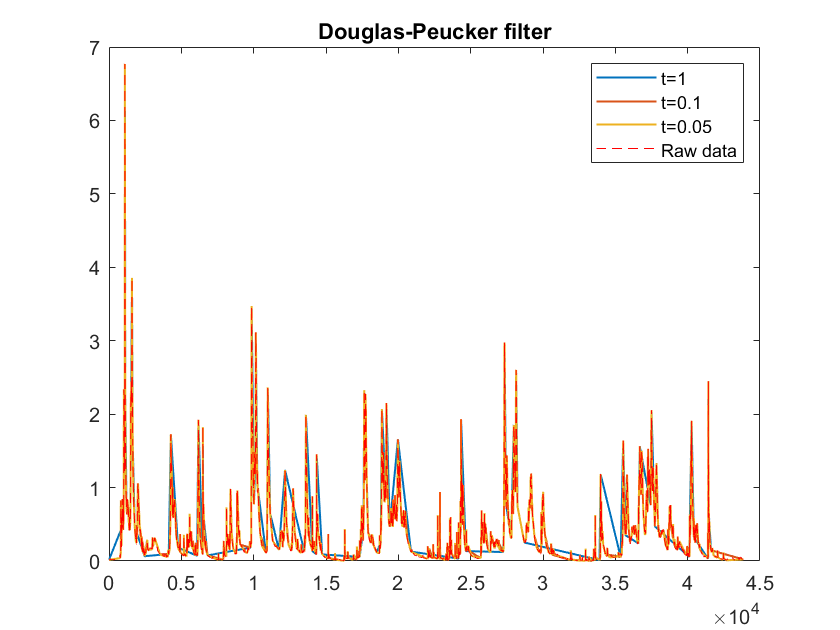

_COL_filled = fillmissing(Q_COL, 'linear');

p = [(1:Datapoint)' Q_COL_filled];

tol = [1 0.1 0.05]; % unit m³/s 
r1 = f_douglas_peucker(p,tol(1));
r2 = f_douglas_peucker(p,tol(2));
r3 = f_douglas_peucker(p,tol(3));

figure
plot(r1(:,1),r1(:,2),'LineWidth',1)
hold on
plot(r2(:,1),r2(:,2),'LineWidth',1)
plot(r3(:,1),r3(:,2),'LineWidth',1)
plot(1:Datapoint, Q_COL,'--','Color','r')
title('Douglas-Peucker filter')
legend('t=1','t=0.1','t=0.05','Raw data')
hold off

In general, moving average filter with all the window sizes reasonably fits the raw data without much deviation. It agrees very well with the trend and amplitude. While with the Douglas-Peucker filter, only smoothed data with low tolerance fits reasonably well to the raw data. The data t = 1 has highest deviation among all results. Concerning the fast changing trend of the raw data, Douglas-Peucker filter is less 'smooth' while moving average appears fits better in curve. 

Concerning particular the period form 9. Dec 2014 – 3. February 2015 with the rising discharge, moving average data smooth the sharp peak and the amplitude of the peak is suppressed in different extends depends on the moving window size. Nonetheless, with Douglas-Peucker filter the peak values are well preserved without much suppression. It is important because if the rising discharge represents the flood risk, the amplitude of extreme values are meaningful to the prediction and mitigation of the event. Thus, Douglas-Peucker filter fits better when flood risk is the concern when hydrological time series data is analysed.